clear 
clc

## Parameters Pre-setting

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 10E6;                      % sample rate
wt = primes(512)                % generate prime number

wt =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97   101   103   107   109   113   127   131   137   139   149   151   157   163   167   173   179   181   191   193   197   199   211   223   227   229


Fin = Fs * wt / 1024            % input frequency (Hz)

Fin = 	1.0e+06 *

    0.0195    0.0293    0.0488    0.0684    0.1074    0.1270    0.1660    0.1855    0.2246    0.2832    0.3027    0.3613    0.4004    0.4199    0.4590    0.5176    0.5762    0.5957    0.6543    0.6934    0.7129    0.7715    0.8105    0.8691    0.9473    0.9863    1.0059    1.0449    1.0645    1.1035    1.2402    1.2793    1.3379    1.3574    1.4551    1.4746    1.5332    1.5918    1.6309    1.6895    1.7480    1.7676    1.8652    1.8848    1.9238    1.9434    2.0605    2.1777    2.2168    2.2363


Ron0 = 6.5*16;                  % for m*(W/L) = 2*3u/200n
NUM_FRE = length(wt);           % number of frequency
NUM_SAM = 1024;                 % number of sample point

## Reading simulation waveform

CSVFILE = 'SD_Exchange_Voutd_Sampled.csv';
opts = detectImportOptions(CSVFILE);
preview(CSVFILE, opts)

ans = 8×194 table
    Vout_sampled_fin_19531_25_X    Vout_sampled_fin_19531_25_Y    Vout_sampled_fin_29296_88_X    Vout_sampled_fin_29296_88_Y    Vout_sampled_fin_48828_12_X    Vout_sampled_fin_48828_12_Y    Vout_sampled_fin_68359_38_X    Vout_sampled_fin_68359_38_Y    Vout_sampled_fin_107421_9_X    Vout_sampled_fin_107421_9_Y    Vout_sampled_fin_126953_1_X    Vout_sampled_fin_126953_1_Y    Vout_sampled_fin_166015_6_X    Vout_sampled_fin_166015_6_Y    Vout_sampled_fin_185546_9_X    Vout_sampled_fin_185546_9_Y    Vout_sampled_fin_224609_4_X    Vout_sampled_fin_224609_4_Y    Vout_sampled_fin_283203_1_X    Vout_sampled_fin_283203_1_Y    Vout_sampled_fin_302734_4_X    Vout_sampled_fin_302734_4_Y    Vout_sampled_fin_361328_1_X    Vout_sampled_fin_361328_1_Y    Vout_sampled_fin_400390_6_X    Vout_sampled_fin_400390_6_Y    Vout_sampled_fin_419921_9_X    Vout_sampled_fin_419921_9_Y    Vout_sampled_fin_458984_4_X    Vout_sampled_fin_458984_4_Y    Vout_sampled_fin_517578_1_X    Vout_sampled_fin_

opts.SelectedVariableNames = 2 : 2 : NUM_FRE*2;
M = readmatrix(CSVFILE, opts);
M(end,:) = [];

## Check the read data

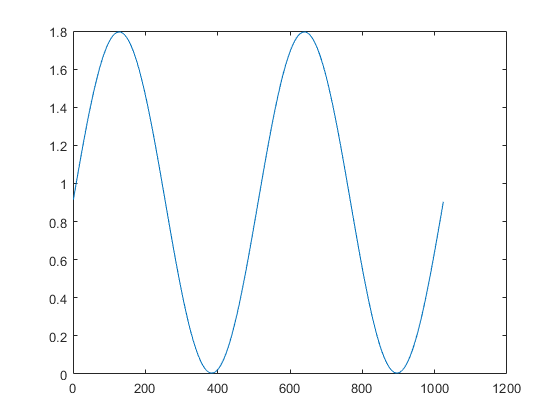

plot(M(:, 1))

[r, harmpow, harmfre] = thd(repmat(M(:,end),16,1 ), Fs, 5, 'aliased')

r = -48.2512

harmpow =    -4.0573
  -55.8152
  -54.9352
  -80.7743
  -74.2476


harmfre = 	1.0e+06 *

    4.9707
    0.0586
    4.9121
    0.1172
    4.8535


## Get THD from the signal

HD3_simulation = zeros(1, NUM_FRE);
for i = 1:NUM_FRE
    [~, harmpow, ~] = thd(repmat(M(:,i), 4, 1), Fs, 5, 'aliased');
    HD3_simulation(i) = harmpow(3) - harmpow(1);
end

HD_temp = getHD_new(Ron0, V0, C1, Fin, -1.15);
HD3_calculation = reshape(HD_temp(1,2,:), 1, NUM_FRE);


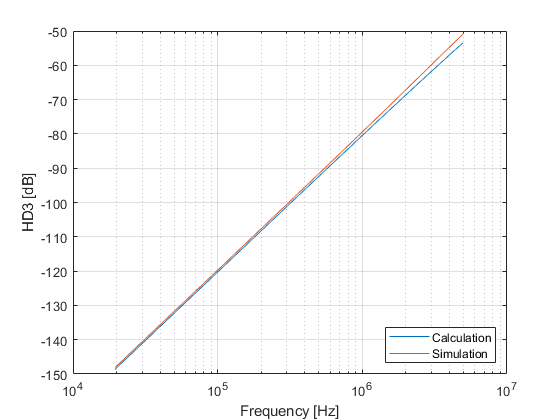

figure
semilogx(Fin, HD3_calculation);     % need to be calibration
hold on;
semilogx(Fin, HD3_simulation);
grid on;
box on;
xlabel("Frequency [Hz]");
ylabel("HD3 [dB]");
legend({'Calculation', 'Simulation'}, "Location", "southeast")